clc;
clear all;
close all;

%% Input parameters to record the holograms

lambda = 0.532;   %Source's wavelenght in microns
k = 2*pi/lambda;        %Wavenumber in microns
dxy = 4.65;  %Pitch in X and Y direction in microns
numG = 3;

[f,p] = uigetfile("*.bmp","Select holograms",MultiSelect="on");
holos = strcat(p,f)

holos = 1×6 cell array
    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle0.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle60.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo1_angle120.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo2_angle0.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\holo2_angle60.bmp'}    {'C:\Users\Alan Schneider\OneDrive - University of Massachusetts Dartmouth\ALAN\SUMMER PROJECT\CODES\ALAN CODE\OBLIQUE ILLUMINATION\struct IMG\h


% Load the selected holograms into a cell array
numHolograms = length(holos);
holograms = cell(numHolograms, 1);
h = cell(numHolograms, 1);
hFilt = cell(numHolograms, 1);
for i = 1:numHolograms
    holograms{i} = double(imread(holos{i}));
    h{i} = fftshift(fft2(fftshift(holograms{i})));
end

[N,M] = size(holograms{1})

N = 1024

M = 1024

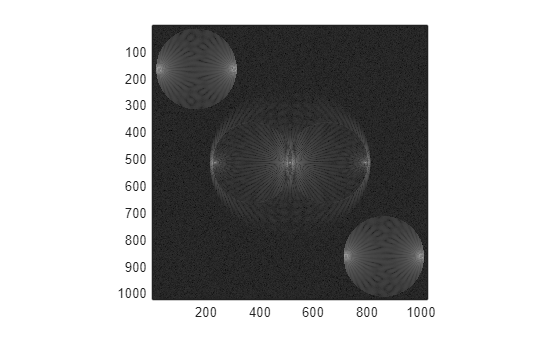

figure; colormap gray;imagesc(abs(h{1}).^0.1);axis image;

%Improvement: better to implement this automatically and with a circular filter
Filter = zeros(N,M);
region = 2; % from GUI
Filter(1:round(N/2-N*0.19),1:round(M/2 -M*0.19)) = 1;  % 2nd quadrant
for i = 1:numHolograms
    hFilt{i} = h{i} .* Filter;
end
g1 = {hFilt{1}, hFilt{4}; 
      hFilt{2}, hFilt{5}; 
      hFilt{3}, hFilt{6}}

g1 = 3×2 cell array
    {1024×1024 double}    {1024×1024 double}
    {1024×1024 double}    {1024×1024 double}
    {1024×1024 double}    {1024×1024 double}


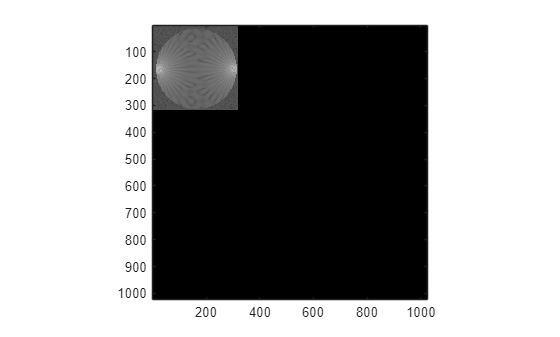

figure; colormap gray;imagesc(abs(hFilt{1}).^0.1);axis image;

H1Filt = hFilt{1};
[x,y] = size(H1Filt);
p1M = min(log(abs(H1Filt(:,1))))

p1M = -Inf

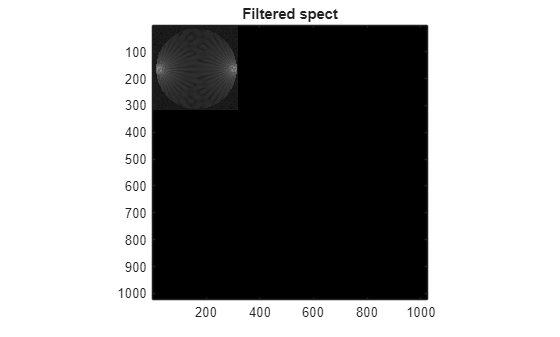

step = 100;
i = x;
while p1M < 0
    p1M = min(log(abs(H1Filt(1:i,1))));
    i = i - step; 
end

TH = 1.1*p1M;
circ2 = circular_filter(H1Filt,TH, N);%  ASK SOFI

% figure; colormap gray; imagesc(BW);axis image, title('Mask to filter +1 term');
figure; colormap gray; imagesc(abs(H1Filt).^.2);axis image;title('Filtered spect');

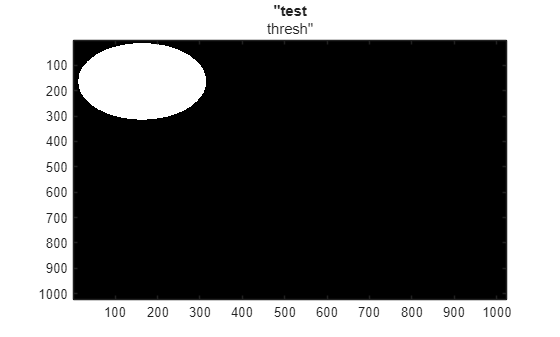

%H1Filt2=circ2.*H1Filt;
figure;colormap gray;imagesc(circ2);title "test thresh"

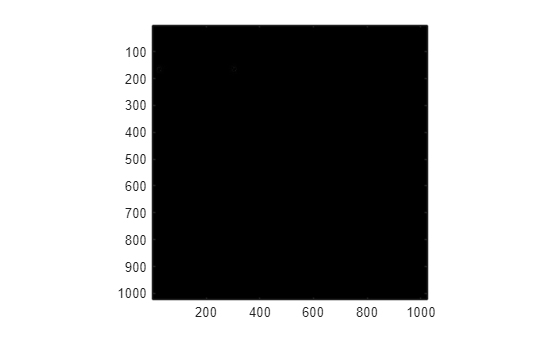

Cmax1 = 305

Rmax1 = 165

Cmax2 = 25

Rmax2 = 165

[Cmax1, Rmax1, Cmax2 , Rmax2] = find_maximum(hFilt{1})

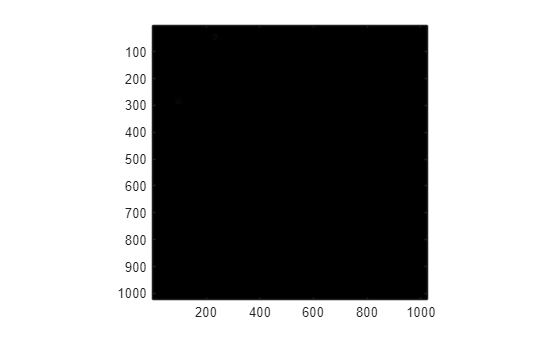

Cmax1_2 = 235

Rmax1_2 = 44

Cmax2_2 = 95

Rmax2_2 = 286

[Cmax1_2, Rmax1_2, Cmax2_2, Rmax2_2] = find_maximum(hFilt{3})

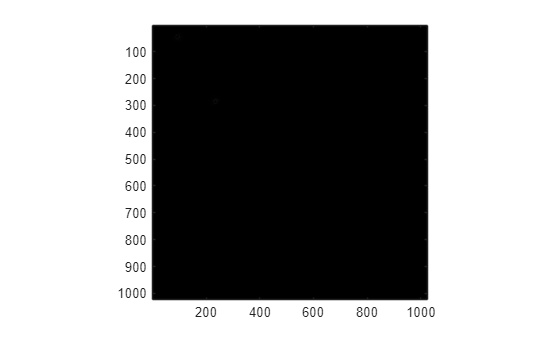

Cmax1_3 = 235

Rmax1_3 = 286

Cmax2_3 = 95

Rmax2_3 = 44

[Cmax1_3, Rmax1_3, Cmax2_3, Rmax2_3] = find_maximum(hFilt{5})

CmaxA = cell(1,numHolograms/2);
CmaxB = cell(1,numHolograms/2);
RmaxA = cell(1,numHolograms/2);
RmaxB = cell(1,numHolograms/2);
orde = cell(numG, 5)

orde = 3×5 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


CmaxA = 1×3 cell array
    {[305]}    {0×0 double}    {0×0 double}


RmaxA = 1×3 cell array
    {[165]}    {0×0 double}    {0×0 double}


CmaxB = 1×3 cell array
    {[25]}    {0×0 double}    {0×0 double}


RmaxB = 1×3 cell array
    {[165]}    {0×0 double}    {0×0 double}


row = 1

col = 1

orde = 3×5 cell array
    {[       1]}    {[     305]}    {[     165]}    {[      25]}    {[     165]}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


o


CmaxA = 1×3 cell array
    {[305]}    {0×0 double}    {[235]}


RmaxA = 1×3 cell array
    {[165]}    {0×0 double}    {[44]}


CmaxB = 1×3 cell array
    {[25]}    {0×0 double}    {[95]}


RmaxB = 1×3 cell array
    {[165]}    {0×0 double}    {[286]}


row = 3

col = 1

orde = 3×5 cell array
    {[       1]}    {[     305]}    {[     165]}    {[      25]}    {[     165]}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {[       3]}    {[     235]}    {[      44]}    {[      95]}    {[     286]}


o


CmaxA = 1×5 cell array
    {[305]}    {0×0 double}    {[235]}    {0×0 double}    {[235]}


RmaxA = 1×5 cell array
    {[165]}    {0×0 double}    {[44]}    {0×0 double}    {[286]}


CmaxB = 1×5 cell array
    {[25]}    {0×0 double}    {[95]}    {0×0 double}    {[95]}


RmaxB = 1×5 cell array
    {[165]}    {0×0 double}    {[286]}    {0×0 double}    {[44]}


row = 2

col = 2

orde = 3×5 cell array
    {[1]}    {[305]}    {[165]}    {[25]}    {[165]}
    {[2]}    {[235]}    {[286]}    {[95]}    {[ 44]}
    {[3]}    {[235]}    {[ 44]}    {[95]}    {[286]}


o


for i = 1:2:numHolograms
    [CmaxA{i}, RmaxA{i}, CmaxB{i} , RmaxB{i}] = find_maximum(hFilt{i})

    if ~isempty(CmaxB{i})
        [row, col] = find(cellfun(@(x) isequal(x,hFilt{i}), g1))
        orde{row,1} = row;
        orde{row,2} = CmaxA{i};
        orde{row,3} = RmaxA{i};
        orde{row,4} = CmaxB{i};
        orde{row,5} = RmaxB{i}
        disp("o")
    end
end

paso = 0.01; %rad
C = zeros(N,M);
F = zeros(N,M);

for i = 1:numG
    %b = hFilt{4};
    [std_temp_gplus, std_temp_gminus, angles, FTHolo] = minimization(g1{i,1},g1{i,2} ,paso, orde{i,2}, orde{i,3}, orde{i,4} , orde{i,5});
    figure(10), log(abs(std_temp_gplus)), title 'metric gplus'
    figure(20), log(abs(FT(std_temp_gplus))), title 'metric gplus',colormap gray
    %figure(20), plot(angles,std_temp_gminus), title 'metric gminus'
    [circ1_Gplus,Gplus] = demodulation_Gplus(std_temp_gplus, angles,FTHolo, dxy, lambda,  circ2);
    [circ1_Gminus,Gminus] = demodulation_Gminus(std_temp_gminus, angles,FTHolo, dxy, lambda, circ2);
    F = normalization_FT(Gplus) + normalization_FT(Gminus) + F;
    C = circ1_Gplus + circ1_Gminus + C;

end

   629

Elapsed time is 49.746829 seconds.


ans =    -1.8570   -1.8885   -1.9213   -1.9552   -1.9906   -2.0273   -2.0657   -2.1058   -2.1477   -2.1917   -2.2379   -2.2866   -2.3381   -2.3926   -2.4505   -2.5124   -2.5786   -2.6499   -2.7271   -2.8112   -2.9034   -3.0057   -3.1201   -3.2501   -3.4001   -3.5775   -3.7939   -4.0702   -4.4487   -5.0231   -5.6506   -5.0159   -4.4512   -4.0801   -3.8102   -3.5996   -3.4276   -3.2828   -3.1580   -3.0485   -2.9512   -2.8638   -2.7844   -2.7119   -2.6452   -2.5836   -2.5263   -2.4728   -2.4227   -2.3756


ans =    -7.1208   -6.5601   -6.5573   -6.8248   -6.3277   -6.1453   -6.3751   -6.1554   -5.9523   -6.1713   -6.1346   -5.9300   -6.1572   -6.2978   -6.0734   -6.2996   -6.7135   -6.4199   -6.5256   -7.2370   -7.0006   -6.5652   -6.6878   -6.9763   -6.3384   -6.1871   -6.4638   -6.1423   -5.9398   -6.1993   -6.0929   -5.8743   -6.1398   -6.2256   -5.9743   -6.2444   -6.6186   -6.2708   -6.4560   -7.3533   -6.8585   -6.5435   -6.8129   -7.2127   -6.3415   -6.1961   -6.5725   -6.1264   -5.8933   -6.2128


   629



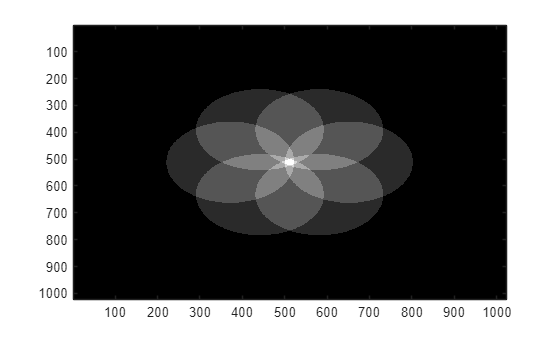


figure(20), imagesc(C), colormap gray

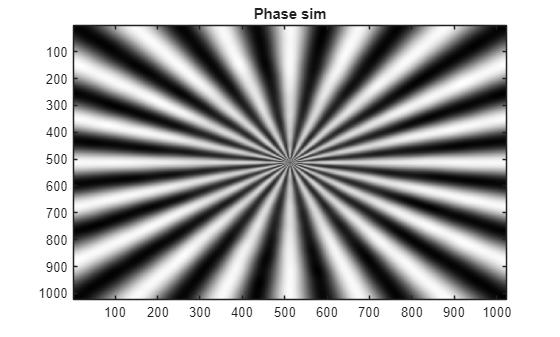

gsim = fftshift(ifft2(fftshift(F)));
figure, imagesc(angle(gsim)), colormap gray, title('Phase sim')

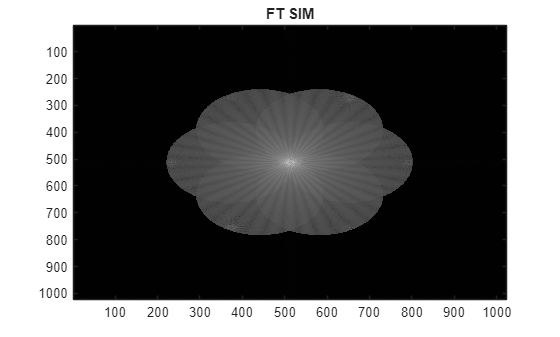

figure, imagesc(abs(F).^0.1), colormap gray, title('FT SIM')

function [theta , profile] = perfil_circular(phase, circle_radius)

% Obtener dimensiones de la imagen
[rows, cols] = size(phase);
center = ([rows+1, cols+1] / 2); % Centro de la imagen

% Definir el radio del círculo a analizar (ajustar según necesidad)


% Definir los ángulos para el círculo
theta = linspace(0, 2*pi, 360); % 360 puntos para cubrir el círculo

% Obtener coordenadas del círculo
x_coords = round(center(2) + circle_radius * cos(theta));
y_coords = round(center(1) + circle_radius * sin(theta));

% Evitar índices fuera de la imagen
valid_idx = (x_coords > 0 & x_coords <= cols) & (y_coords > 0 & y_coords <= rows);
x_coords = x_coords(valid_idx);
y_coords = y_coords(valid_idx);
theta = theta(valid_idx); % Mantener los ángulos válidos

% Obtener valores de intensidad a lo largo del círculo
profile = zeros(size(theta));
for i = 1:length(theta)
    profile(i) = phase(y_coords(i), x_coords(i));
end

% % Display the original image with the ring overlaid
figure;
imshow(phase, []);
hold on;
plot(center(2) + circle_radius * cos(theta), center(1) + circle_radius * sin(theta), 'b', 'LineWidth', 1);
title('Image with Ring Overlay');
end




function circ2 = circular_filter(H1Filt,TH, N)
BW = imbinarize(abs(H1Filt).^.2, TH);
BW = bwareafilt(BW, 1);
BW_filled = imfill(BW, 'holes');
edges = edge(BW_filled, 'Canny');

[y,x] = find(edges);
A = [-2*x, -2*y, ones(size(x))];
b = -(x.^2 + y.^2);
params = A\b;
center(1) = params(1);
center(2) = params(2);
radius = ceil(sqrt(center(1)^2 + center(2)^2 - params(3)));

% Visualización clara de resultados
% figure; imshow(BW); hold on;
% viscircles([center(1), center(2)], radius, 'EdgeColor','b');
% plot(center(1), center(2), 'r+', 'MarkerSize', 20, 'LineWidth', 2);

circ2 = ones(N);
for r = 1:N
    for p = 1:N
        if sqrt((r-center(2))^2+(p-center(1))^2)>radius
            circ2(r,p) = 0;
        end
    end
end
% Circ_filtered_spectrum1 = ft_filtered_holo.*circ;
end


function Ft_norm = normalization_FT(Given_FT)
Ft_Gminus = fftshift(fft2(fftshift(Given_FT)));
Ft_norm = (Ft_Gminus - min(min(Ft_Gminus)))/(max(max(Ft_Gminus)) - min(min(Ft_Gminus)));
end 


function [circ1,zero_phase6] = demodulation_Gminus(std_temp_gminus, angles,FTHolo, dxy, lambda, circ2)
posicion = find(std_temp_gminus == min(std_temp_gminus));
theta_final = [0, angles(posicion)];
[Gdemod] =  demComp2SIDHM(theta_final, FTHolo);
Gminus_demod = Gdemod(:,:,2);

gminus = fftshift(ifft2(fftshift(Gminus_demod)));
gminus = gminus*-1;
% ref_minus = phase_rec(gminus, dxy, dxy, lambda, region, false);
[ref_minus] = phase_rec(gminus, dxy, dxy, lambda, circ2);
Gminus = gminus .*ref_minus;

Gminus1 = FT(Gminus);
% Find max in A_before
[~, idx_before] = max(log(abs(Gminus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gminus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gminus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gminus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ1 = circshift(circ2, [delta_row, delta_col]);

FT_centrada6 = FT(Gminus).*circ1;
Centered_complex_field6 = IFT(FT_centrada6);
zero_phase6 = (Centered_complex_field6);
end


function [circ1,zero_phase6] = demodulation_Gplus(std_temp_gplus, angles,FTHolo, dxy, lambda, circ2)
posicion = find(std_temp_gplus == min(std_temp_gplus));
theta_final = [0, angles(posicion)];
[Gdemod] =  demComp2SIDHM(theta_final, FTHolo);
Gplus_demod = Gdemod(:,:,1);
gplus = fftshift(ifft2(fftshift(Gplus_demod)));
gplus = gplus*-1;
[ref_gplus] = phase_rec(gplus, dxy, dxy, lambda, circ2);
Gplus = gplus .* ref_gplus;

Gminus1 = FT(Gplus);
% Find max in A_before
[~, idx_before] = max(log(abs(Gplus_demod(:)).^2));
[row_before, col_before] = ind2sub(size(Gplus_demod), idx_before);

% Find max in A_after
[~, idx_after] = (max(log(abs(Gminus1(:)).^2)));
[row_after, col_after] = ind2sub(size(Gminus1), idx_after);

% Calculate displacement
delta_row = row_after - row_before;
delta_col = col_after - col_before;
circ1 = circshift(circ2, [delta_row, delta_col]);

FT_centrada6 = FT(Gplus).*circ1;
Centered_complex_field6 = IFT(FT_centrada6);
zero_phase6 = (Centered_complex_field6);
end

function [std_temp_gplus, std_temp_gminus, angles, FTHolo]=minimization(H1Filt, H2Filt,paso, Cmax1, Rmax1, Cmax2 , Rmax2)
FTHolo(:,:,1) = H1Filt;
FTHolo(:,:,2) = H2Filt;

angles = 0.0001:paso:2*pi;
disp(length(angles))
std_temp_gplus = ones(1,length(angles));
std_temp_gminus = ones(1,length(angles));

tic
parfor i = 1:length(angles)
    v = angles(i);
    % Demodulation using the optimized values
    theta_final = [0, v];
    [Gdemod] =  demComp2SIDHM(theta_final, FTHolo);
    Gplus_demod = Gdemod(:,:,1);
    Gminus_demod = Gdemod(:,:,2);
    std_temp_gplus(1,i) =  abs(Gplus_demod(Rmax2,Cmax2))/abs(abs(Gplus_demod(Rmax2,Cmax2)) + abs(Gplus_demod(Rmax1,Cmax1)));
    std_temp_gminus(1,i) =  abs(Gminus_demod(Rmax1,Cmax1))/abs(abs(Gminus_demod(Rmax2,Cmax2)) + abs(Gminus_demod(Rmax1,Cmax1)));
end
toc
end


function [Cmax1, Rmax1, Cmax2 , Rmax2] = find_maximum(H1Filt)
%figure; colormap gray; imagesc(abs(H1Filt));axis image;
AbsFT = abs(H1Filt);
maxValue = max(AbsFT(:));%value of the maximum peaks
[rowsofMaxPk, colsofMaxPk] = find(AbsFT == maxValue);

Cmax1 = colsofMaxPk;%Horizontal position of the peak of Dplus
Rmax1 = rowsofMaxPk;%Vertical position of the peak of Dplus

clear maxValue rowsofMaxPk colsofMaxPk

AbsFT(Rmax1-2:Rmax1+2,Cmax1-2:Cmax1+2) = 0;%% ASK SOFI
figure; colormap gray; imagesc(AbsFT);axis image;
maxValue = max(AbsFT(:));%value of the maximum peaks
[rowsofMaxPk, colsofMaxPk] = find(AbsFT == maxValue);

Cmax2 = colsofMaxPk;%Horizontal position of the peak of Dminus
Rmax2 = rowsofMaxPk;%Vertical position of the peak of Dminus

clear AbsFT maxValue rowsofMaxPk colsofMaxPk
end



function  [ref] = phase_rec(filename, dx, dy, lambda, circ)

% Main function to perform phase reconstruction
holo = filename;

% Get the size of the hologram
[N,M] = size(holo);
% Create a meshgrid for the hologram
[m,n] = meshgrid(-M/2:M/2-1,-N/2:N/2-1);

% Calculate the Fourier Transform of the hologram and shift the zero-frequency component to the center
ft_holo = fftshift(fft2(fftshift(holo)));

% Initialize a filter with zeros
filter = zeros(N,M);
% Create a filter mask for the desired region
filter(2:round(N/2-(N*0.18)),2:M) = 1; % 1nd quadrant

% Apply the filter to the Fourier Transform of the hologram
ft_filtered_holo = ft_holo .* filter;

Circ_filtered_spectrum1 = ft_filtered_holo.*circ;

[~,idx] = max(Circ_filtered_spectrum1(:));
% Get the maximum values of fx and fy
[fy_max,fx_max] = ind2sub([N,M],idx);

% Find the maximum value in the filtered spectrum
% Define wavenumber
k = 2 * pi / lambda;
% Calculate the center frequencies for fx and fy
fx_0 = M/2;
fy_0 = N/2;

% Calculate the angles for the compensation wave
theta_x = asin((fx_0 - fx_max +1) * lambda / (M * dx));
theta_y = asin((fy_0 - fy_max +1) * lambda / (N * dy));
% Calculate the reference wave
ref = exp(1i * k * (sin(theta_x) * m * dx + sin(theta_y) * n * dy));
end


function [D] = demComp2SIDHM(theta, H)

% Initialize some useful values
[X, Y, no] = size(H); % number of training examples

% You need to return the following variables correctly 
D = zeros(X,Y,no);

M = 1/2*[exp(1i*theta(1)) exp(-1i*theta(1));exp(1i*theta(2)) exp(-1i*theta(2))];
% Minv = pinv(M);
Minv = inv(M);

D(:,:,1) = Minv(1,1).*H(:,:,1) + Minv(1,2).*H(:,:,2);
D(:,:,2) = Minv(2,1).*H(:,:,1) + Minv(2,2).*H(:,:,2);

end
